%%%%% Bob Wilson & Anne Collins
%%%%% 2018
%%%%% Code to produce figure 5 in submitted paper "Ten simple rules for the
%%%%% computational modeling of behavioral data"



clearvars -except all_params best_params rew_params pun_params mix_params

addpath('./SimulationFunctions')
addpath('./AnalysisFunctions')
addpath('./HelperFunctions')
addpath('./FittingFunctions')
addpath('./LikelihoodFunctions')

CM = zeros(3);
true_b = all_params(:,1);

Unrecognized function or variable 'all_params'.

true_eps = all_params(:,2);
true_alpha = all_params(:,3);
true_beta = all_params(:,4);

T = 105; %35 by block or 105 for all together
%set the mu and reversal trials for correct condition
%reversal_timings = data.reversal_timings;
%[mu, reversal_trials] = reversal_condition(reversal_timings);
mu = [0.8 0.2];
%reversal_trials = [13, 25];
reversal_trials = [13, 25, 36, 48, 60, 71, 83, 95];
for count = 1:100 %  your number of reps - better to put 100
    count

    figure(1); clf;
    FM = round(100*CM/sum(CM(1,:)))/100;
    t = imageTextMatrix(FM);
    set(t(FM'<0.3), 'color', 'w')
    hold on;
    [l1, l2] = addFacetLines(CM);
    set(t, 'fontsize', 22)
    title(['count = ' num2str(count)]);
    set(gca, 'xtick', [1:5], 'ytick', [1:5], 'fontsize', 28, ...
        'xaxislocation', 'top', 'tickdir', 'out')
    xlabel('fit model')
    ylabel('simulated model')
      
    drawnow
    % Model 1
    b = randi(length(true_b));
    true_b_pick = true_b(b);
    sim_b = abs(true_b_pick * randn(1,1));
    if sim_b >= 1
        sim_b = 1
    end
    %b = rand;
% Fill in with parameters from your fit model. 
    [a, r] = simulate_M1random_v1(T, mu, sim_b, reversal_trials);

    %if block == 'punishment'
        %r = r - 1;
    %elseif block == 'mixed'
        %r(r==0) = -1
    %end
%     r1 = find(r==0);
%     r = double(r);
%     r(r1) = -1;
    [BIC, iBEST, BEST] = fit_all_v1(a, r);
    % this provides BIC for the 5 models,identity of best of the models
    % (1-5) and normalised BEST is the same but a vector of 5 values
    CM(1,:) = CM(1,:) + BEST;
    all_sim_b(count) = sim_b; 

    % Model 2
    epsilon = randi(length(true_eps));
    true_eps_pick = true_eps(epsilon);
    sim_eps = abs(true_eps_pick * randn(1,1));
    if sim_eps >= 1
        sim_eps = 1
    end
    %epsilon = rand;
    [a, r] = simulate_M2WSLS_v1(T, mu, sim_eps, reversal_trials);
    %r = r-1;
%     r1 = find(r==0);
%     r = double(r);
%    r(r1) = -1;
    [BIC, iBEST, BEST] = fit_all_v1(a, r);
    CM(2,:) = CM(2,:) + BEST;
    all_sim_eps(count) = sim_eps;

    % Model 3
         
    %alpha = rand;
    %beta = 1+exprnd(1);
    alpha = randi(length(true_alpha));
    true_alpha_pick = true_alpha(alpha);
    sim_alpha = abs(true_alpha_pick * randn(1,1));
    if sim_alpha >= 1
        sim_alpha = 1
    end   

   beta = randi(length(true_beta));
   true_beta_pick = true_beta(beta);
   sim_beta = abs(true_beta_pick * randn(1,1));
    %sim_beta = 5;
    [a, r] = simulate_M3RescorlaWagner_v1(T, mu, sim_alpha, sim_beta, reversal_trials);
    all_as(count,:) = a;
    r = double(r)
    all_rs(count,:) = r;
%     r1 = find(r==0);
%     r = double(r);
%     r(r1) = -1;
    %r = r-1;
%     r(r==0)=-1;
    [BIC, iBEST, BEST] = fit_all_v1(a, r);
    CM(3,:) = CM(3,:) + BEST;
    all_sim_alphas(count) = sim_alpha;
    all_sim_betas(count) = sim_beta;
    
end
%all_CMs{agent,1} = CM;


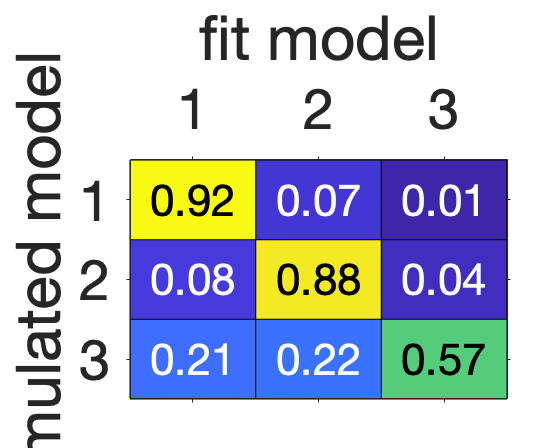

figure(1); 
title('')
set(gcf, 'Position', [811   417   500   400])
set(gca, 'fontsize', 28);



% [Xf, LL, BIC] = fit_M1random_v1(a, r);
% [Xf, LL, BIC] = fit_M2WSLS_v1(a, r);
% [Xf, LL, BIC] = fit_M3RescorlaWagner_v1(a, r);
% [Xf, LL, BIC] = fit_M4CK_v1(a, r);
% [Xf, LL, BIC] = fit_M5RWCK_v1(a, r);